# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 120; % # sample points
A = 17; % Magnitude/Amplitude of droplet
% c1 = 0.0010;  
% c2 = 0.0196;
c1 = 0.0010;  
c2 = 0.0196;

c3 = 0.0013;
c4 = 0.0108;

tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
x0 = 7.5;
x1 = 15;
xO0 = 5;
aa=-5;
bb=5;
cc=1;

**Target Shape **`h_target`

a=round(aa/dx+N/2);
b=round(bb/dx+N/2);
c=cc*ones(size(X));

% h_region = ones(size(X));
% h_region(1:(a+b)/2) = (c(1:(a+b)/2) + tanh(X(1:(a+b)/2)+bb)).*(1./abs(X((a+b)/2)-X(1:(a+b)/2)+1));
% h_region((a+b)/2+1:end) = (c((a+b)/2+1:end) - tanh(X((a+b)/2+1:end)+aa)).*(1./abs(X((a+b)/2)-X((a+b)/2+1:end)-1));
% h_region(1:a) = ((1-y0)./abs(1+X(a)-X(1:a))).*c(1:a)+y0;
% h_region(b:end) = ((1-y0)./abs(X(b)-X(b:end)-1)).*c(b:end)+y0;

% h_region = .5*ones(size(X));

h_region = ones(size(X));
h_region(1:a) = c(1:a) + tanh((X(1:a)-aa)./(2*x0));
h_region(a+1:(a+b)/2) = c(a+1:(a+b)/2) + tanh((X(a+1:(a+b)/2)-aa)./(.5*x0));
h_region((a+b)/2+1:b) = c((a+b)/2+1:b) - tanh((X((a+b)/2+1:b)-bb)./(.5*x0));
h_region(b+1:end) = c(b+1:end) - tanh((X(b+1:end)-bb)./(2*x0));

target = [a,b,h_region];

## **2) **

**Solutions**

Inside

[~,~,~,~,H0_Possition,myObjective_Possition,conds_Sol_Possition,...
    ~,~,output_Possition,history_Possition,History_Possition,h_Sol_Possition,H_Sol_Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c1,c2,x0,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          82.6336         
     1            2          82.6336         initial simplex
     2            4          76.3871         expand
     3            6          58.1159         expand
     4            8          19.1754         expand
     5           10          15.3681         reflect
     6           12          15.3681         contract inside
     7           14          15.1176         contract inside
     8           16          15.1176         contract inside
     9           18          15.1176         contract inside
    10           20          15.1176         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 




[~,~,~,~,H0_Disjoining,myObjective_Disjoining,conds_Sol_Disjoining,...
    ~,~,output_Disjoining,history_Disjoining,History_Disjoining,h_Sol_Disjoining,H_Sol_Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          15.1176         
     1            3          13.8566         initial simplex
     2            5          8.23184         expand
     3            7          3.66347         expand
     4            9         0.605973         expand
     5           10         0.605973         reflect
     6           12         0.605973         contract inside
     7           14         0.605973         contract outside
     8           15         0.605973         reflect
     9           17         0.605973         contract inside
    10           19         0.548704         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 




[~,~,~,~,H_1Possition,~,conds_Sol_1Possition,...
    ~,~,output_1Possition,history_1Possition,History_1Possition,h_Sol_1Possition,H_Sol_1Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c1,c2,x1,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          92.8172         
     1            2          92.8172         initial simplex
     2            4          91.4137         expand
     3            6          88.4826         expand
     4            8          42.6509         expand
     5           10          15.4118         reflect
     6           12          15.4118         contract inside
     7           14          15.1176         contract inside
     8           16          15.1176         contract inside
     9           18          15.1176         contract outside
    10           20          15.1176         contract inside
    11           22          15.1176         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 




[~,~,~,~,H_1Disjoining,myObjective_1Disjoining,conds_Sol_1Disjoining,...
    ~,~,output_1Disjoining,history_1Disjoining,History_1Disjoining,h_Sol_1Disjoining,H_Sol_1Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_1Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          15.1176         
     1            3          13.8566         initial simplex
     2            5          8.23184         expand
     3            7          3.66347         expand
     4            9         0.605973         expand
     5           10         0.605973         reflect
     6           12         0.605973         contract inside
     7           14         0.605973         contract outside
     8           15         0.605973         reflect
     9           17         0.605973         contract inside
    10           19         0.548704         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 



nDisjoin = size(history_Disjoining);
nDisjoin = nDisjoin(1);

nPossition = size(history_Possition);
nPossition = nPossition(1); 

history1 = ones(nDisjoin+nPossition,3);

history1(1:nPossition,2:3) = [c1 c2].*ones(size(history_Possition));
history1(nPossition+1:end,2:3) = history_Disjoining;

history1(1:nPossition,1) = history_Possition;
history1(nPossition+1:end,1) = history_Possition(end).*ones(size(History_Disjoining));

History1 = [History_Possition;History_Disjoining];


nDisjoin_1 = size(history_1Disjoining);
nDisjoin_1 = nDisjoin_1(1);

nPossition_1 = size(history_1Possition);
nPossition_1 = nPossition_1(1); 

history1_1 = ones(nDisjoin_1+nPossition_1,3);

history1_1(1:nPossition_1,2:3) = [c1 c2].*ones(size(history_1Possition));
history1_1(nPossition_1+1:end,2:3) = history_1Disjoining;

history1_1(1:nPossition_1,1) = history_1Possition;
history1_1(nPossition_1+1:end,1) = history_1Possition(end).*ones(size(History_1Disjoining));

History1_1 = [History_1Possition;History_1Disjoining];

**Inside Figures**

Fig. 0

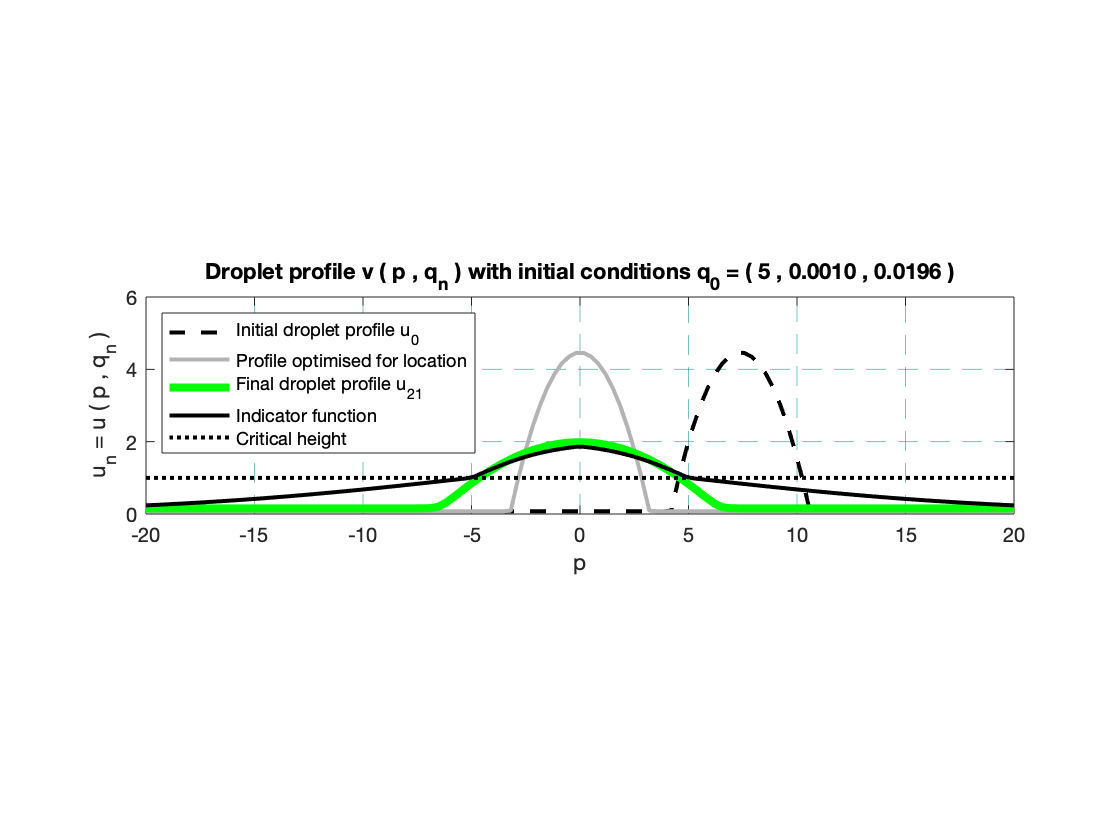

figure;
hold on
plot(X,H0_Possition,'k--','linewidth',2);
plot(X,H0_Disjoining,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_Disjoining,'g-','linewidth',4);
plot(X,h_region,'k-','linewidth',2);
plot(X,ones(size(X)),'k:','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Profile optimised for location',...
    'Final droplet profile u_{21}',...
    'Indicator function',...
    'Critical height',...
    'Location','northwest');
title('Droplet profile v ( p , q_n ) with initial conditions q_0 = ( 5 , 0.0010 , 0.0196 )');
hold off

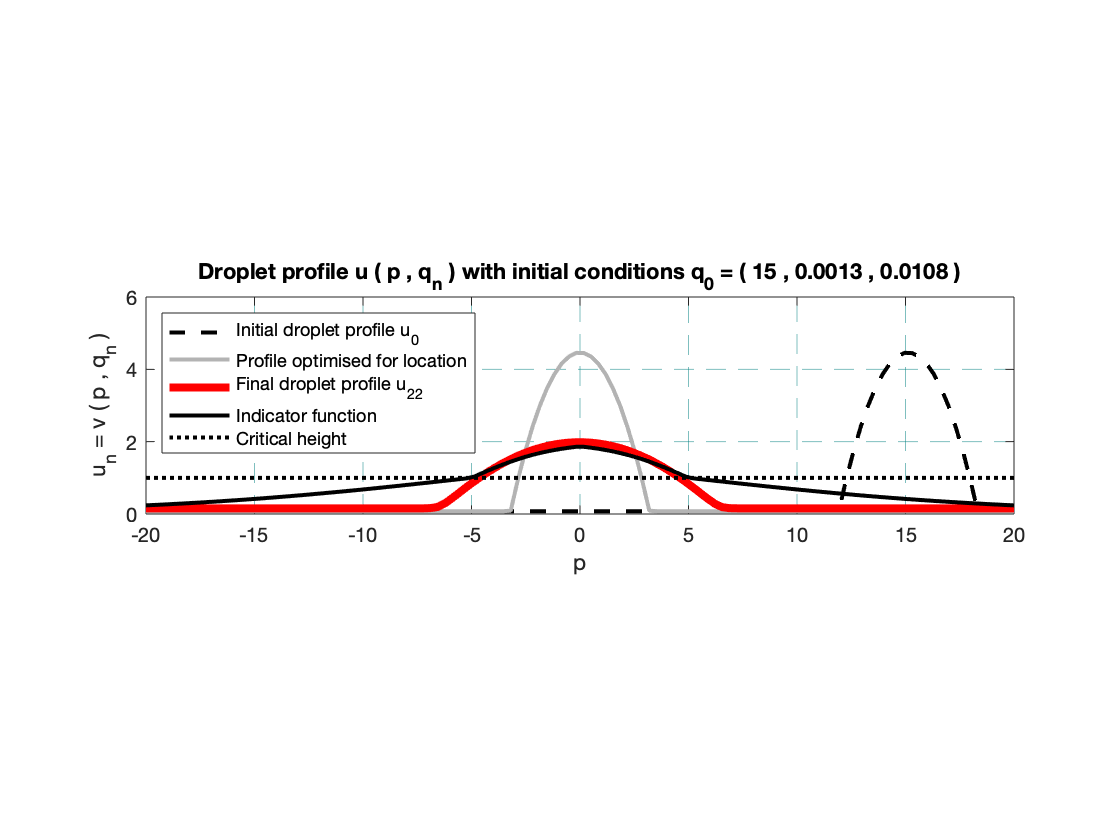


figure;
hold on
plot(X,H_1Possition,'k--','linewidth',2);
plot(X,H_1Disjoining,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_1Disjoining,'r-','linewidth',4);
plot(X,h_region,'k-','linewidth',2);
plot(X,ones(size(X)),'k:','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Profile optimised for location',...
    'Final droplet profile u_{22}',...
    'Indicator function',...
    'Critical height',...
    'Location','northwest');
title('Droplet profile u ( p , q_n ) with initial conditions q_0 = ( 15 , 0.0013 , 0.0108 )');
hold off

**Joint Figures**

Fig. 1

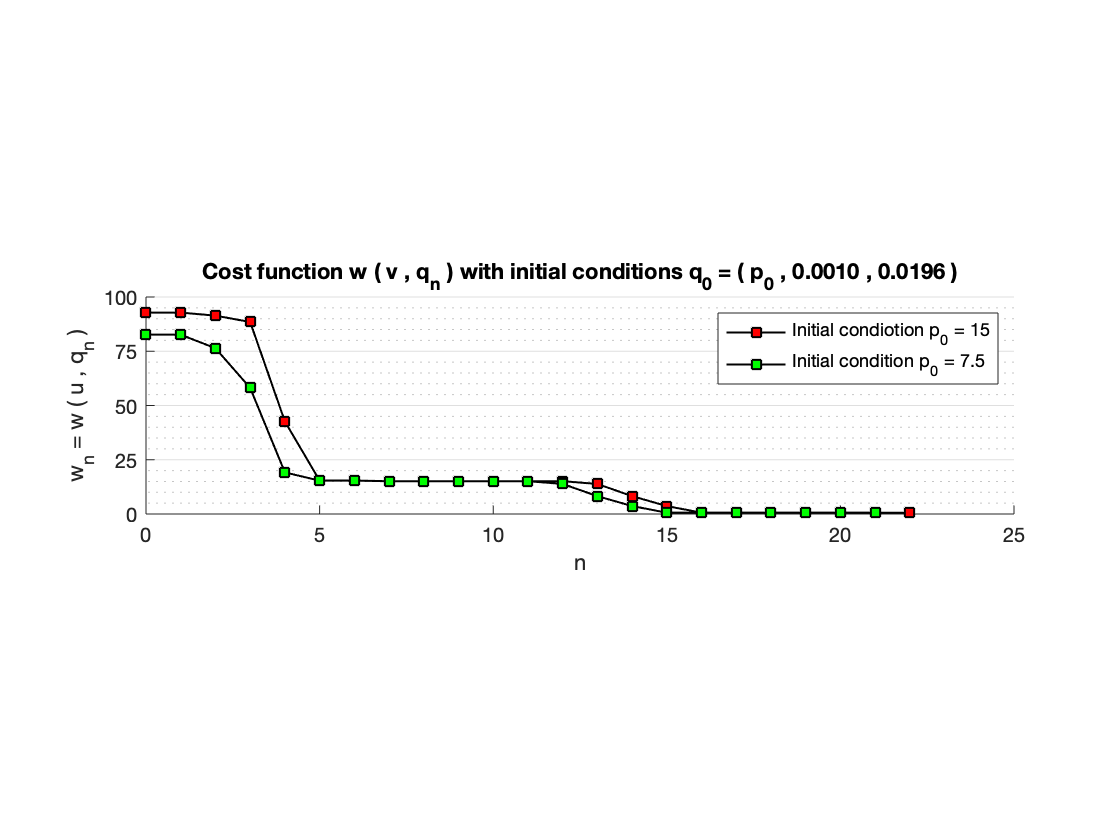


figure;
hold on
plot(0:22,History1_1,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:21,History1,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
ylabel('w_n = w ( u , q_n )');
xlabel('n');
legend('Initial condiotion p_0 = 15','Initial condition p_0 = 7.5','Location','northeast');
title('Cost function w ( v , q_n ) with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 25]);
ylim([0 100]);
set(gca,'xtick',0:5:100);
set(gca,'ytick',0:25:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([4 1 1]);
box off
hold off

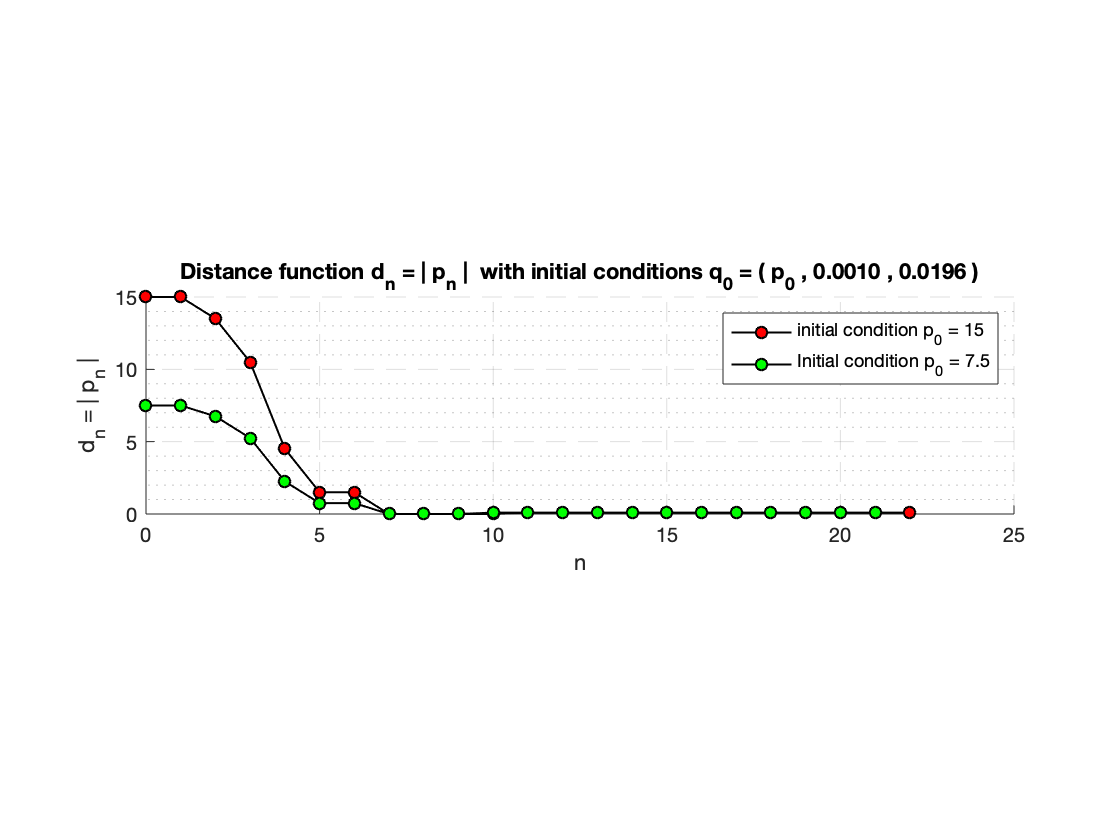


figure;
hold on
plot(0:22,abs(history1_1(:,1)),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:21,abs(history1(:,1)),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
ylabel('d_n = | p_n |');
xlabel('n');
legend('initial condition p_0 = 15','Initial condition p_0 = 7.5','Location','northeast');
title('Distance function d_n = | p_n |  with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 25]);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.XAxisLocation = 'origin';
pbaspect([4 1 1]);
box off
hold off

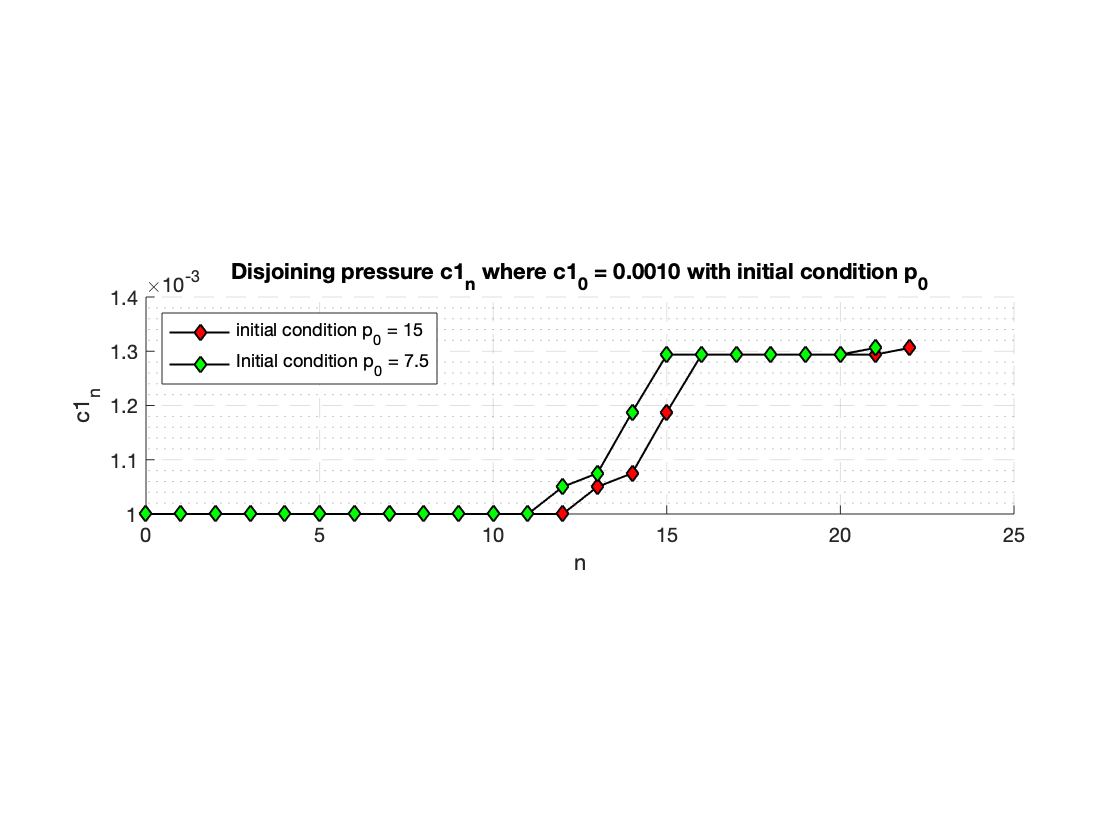



figure;
hold on
plot(0:22,history1_1(:,2),'k-d',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:21,history1(:,2),'k-d',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
pbaspect([4 1 1]);
ylabel('c1_n');
xlabel('n');
title('Disjoining pressure c1_n where c1_0 = 0.0010 with initial condition p_0');
legend('initial condition p_0 = 15','Initial condition p_0 = 7.5','Location','northwest');
xlim([0 25]);
ylim([.001 .0014]);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

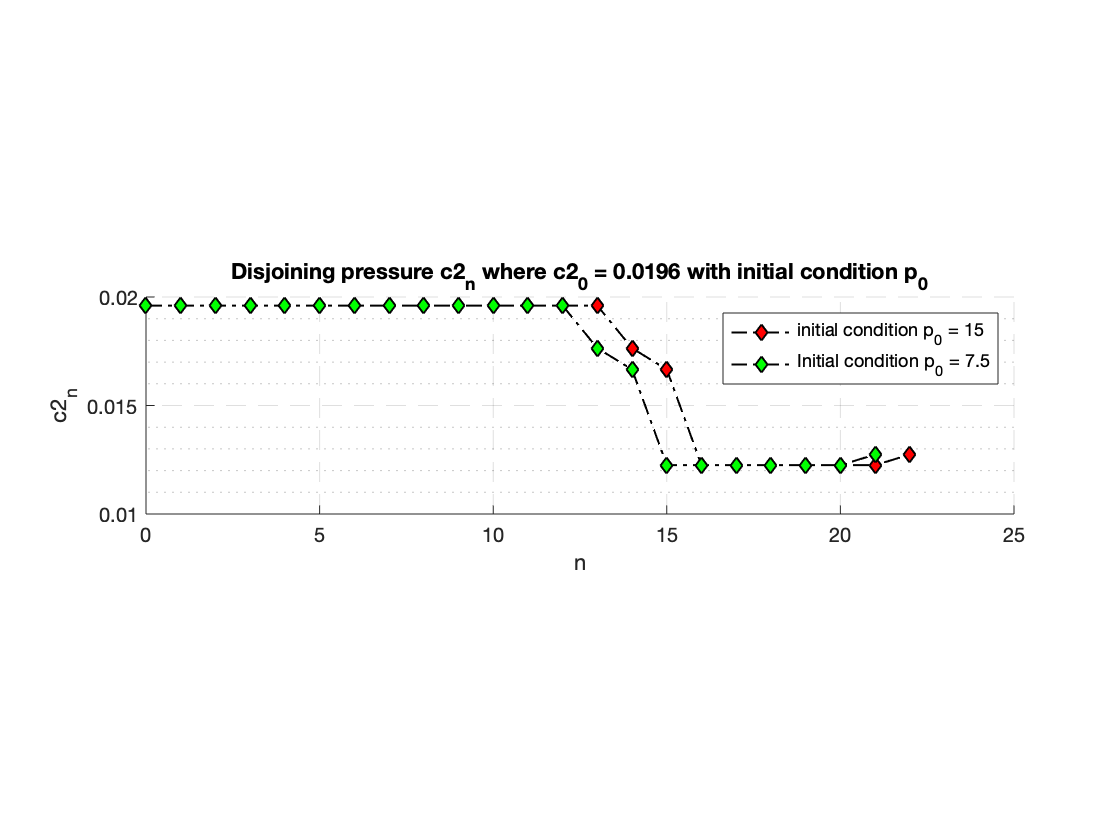



figure;
hold on
plot(0:22,history1_1(:,3),'k-.d',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
pbaspect([4 1 1]);
plot(0:21,history1(:,3),'k-.d',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
ylabel('c2_n');
xlabel('n');
title('Disjoining pressure c2_n where c2_0 = 0.0196 with initial condition p_0');
legend('initial condition p_0 = 15','Initial condition p_0 = 7.5','Location','northeast');
set(gca,'xtick',0:5:100);
xlim([0 25]);
ylim([.01 .02]);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

% 
% n = size(history);
% n1 = n(2)-2;
% 
% dataH = history(:,2:8);
% dataHi = abs(history(:,2:end));
% 
% dataH = history(:,2:8);
% dataHi = abs(history(:,2:end));
% 
% lineH = 0:1:6;
% lineHi = 0:1:n1;
% 
% [px,Sx,mux] = polyfit(lineH,dataH(1,:),1);
% [pc1,Sc1,muc1] = polyfit(lineH,dataH(2,:),1);
% [pc2,Sc2,muc2] = polyfit(lineH,dataH(3,:),1);
% 
% [pHx,delta(1,:)] = polyval(px,lineH,Sx,mux);
% [pHc1,delta(2,:)] = polyval(pc1,lineH,Sc1,muc1);
% [pHc2,delta(3,:)] = polyval(pc2,lineH,Sc2,muc2);
% 
% xi = linspace(0, n1, 100); 
% yxi = interp1(lineHi, dataHi(1,:), xi, 'spline', 'extrap');
% yc1i = interp1(lineHi, dataHi(2,:), xi, 'spline', 'extrap');
% yc2i = interp1(lineHi, dataHi(3,:), xi, 'spline', 'extrap');

% var = [A;N;k;y0]; 
% 
% h = hFinalRegion(history(:,6)',X,var,D1,D2,tSpan);
% H = deval(h,tfinal); 
% 
% h1 = hFinalRegion(history_1(:,6),X,var,D1,D2,tSpan);
% H1 = deval(h1,tfinal);   